## Getting started

Here we will generate the plot displayed in the readme file, which represents the evolution of fuel economy of new cars bewteen 1970 and 1980 (from the carbig dataset). Gramm is used to easily separate data on the basis of the number of cylinders of the cars (here as color), and on the basis of the region of origin of the cars (here as subolot columns). Both the raw data (points) and a glm fit with 95% confidence interval (line+shaded area) are plotted. 

We start by loading the sample data (structure created from the carbig dataset)

load example_data;

We then create a gramm object, provide x (year of production) and y (fuel economy) data, color grouping data (number of cylinders) and select a subset of the data (here excluding rare cars with 3 or 5 cylinders). This command does not plot anything yet.

g=gramm('x',cars.Model_Year, ...
    'y',cars.MPG, ...
    'color',cars.Cylinders, ...
    'subset',cars.Cylinders~=3 & cars.Cylinders~=5);

Then we subdivide the data in subplots horizontally by region of origin using facet_grid()

g.facet_grid([],cars.Origin_Region);

Now that the gramm object is set up with the data, we add plotting elements, starting with the data points

g.geom_point();


Then overlay the linear fits of the data with associated confidence intervals

g.stat_glm();

These two commands allow us to set the proper names for the different elements (axes, colors, columns) and the title of the figure

g.set_names('column','Origin', ...
    'x','Year of production', ...
    'y','Fuel economy (MPG)', ...
    'color','# Cylinders');

g.set_title('Fuel economy of new cars between 1970 and 1982');

After creating the figure, the final command does the actual drawing.

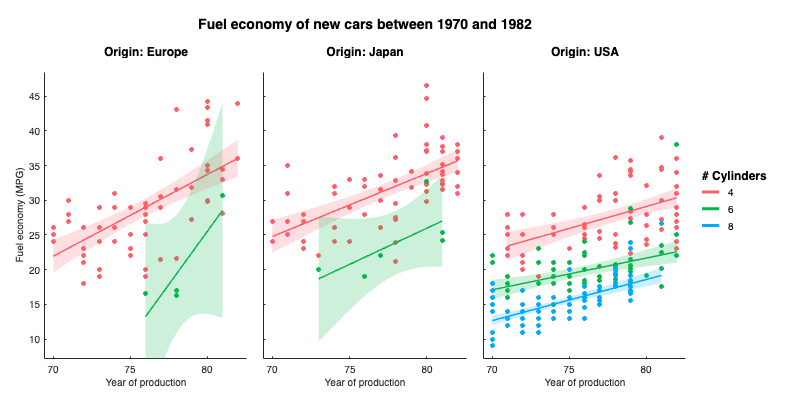

figure('Position',[100 100 800 400]);
g.draw();